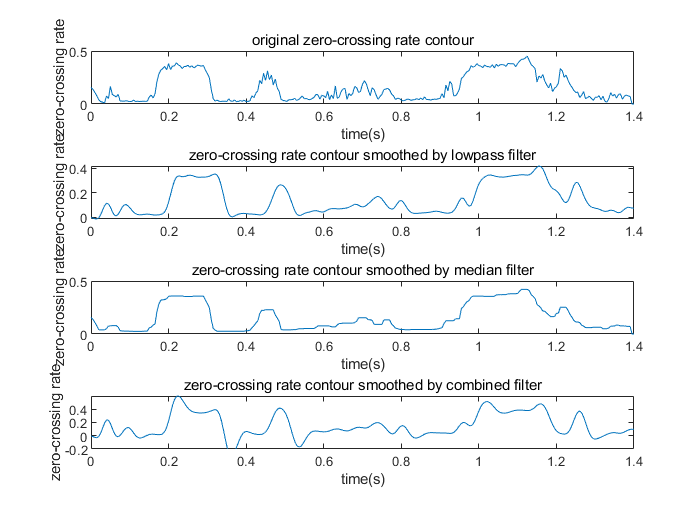

[s,fs]=audioread('test_16k.wav');
N=length(s);
L=0.01*fs;
R=0.005*fs;
window=hamming(L);

%original zero-crossing rate contour
[E,M,Z]=EMZ(s,L,R,window');

%lowpass filter
Hd=lowpass_filter_problem1;
Z_lowpass=filter(Hd,Z);

%median filter
Z_median_7=MedianSmoother(Z,7);
Z_median_5=MedianSmoother(Z_median_7,5);

%combined
%delay=(length(Z)-1)/2;
delay=0;
Z1=filter(Hd,Z_median_5);

Z2=zeros(1,delay+length(Z));
Z2(delay+1:delay+length(Z))=Z;

Z11=zeros(1,delay+length(Z));
Z11(1:length(Z))=Z1;
Z3=Z2-Z11;

Z4=zeros(1,delay+length(Z));
Z4(delay+1:delay+length(Z))=Z1;

Z3_median_7=MedianSmoother(Z3,7);
Z3_median_5=MedianSmoother(Z3_median_7,5);
Z5=filter(Hd,Z3_median_5);

y=Z4+Z5;

figure
subplot(4,1,1);
plot(0:1/fs*R:(N/R-1)/fs*R,Z);
title("original zero-crossing rate contour");
xlabel('time(s)');
ylabel('zero-crossing rate');

subplot(4,1,2);
plot(0:1/fs*R:(N/R-1)/fs*R,Z_lowpass);
title("zero-crossing rate contour smoothed by lowpass filter");
xlabel('time(s)');
ylabel('zero-crossing rate');

subplot(4,1,3);
plot(0:1/fs*R:(N/R-1)/fs*R,Z_median_5);
title("zero-crossing rate contour smoothed by median filter");
xlabel('time(s)');
ylabel('zero-crossing rate');

subplot(4,1,4);
plot(0:N/fs/(length(y)-1):N/fs,y);
title("zero-crossing rate contour smoothed by combined filter");
xlabel('time(s)');
ylabel('zero-crossing rate');
axis([0 1.4 -0.2 0.6]);

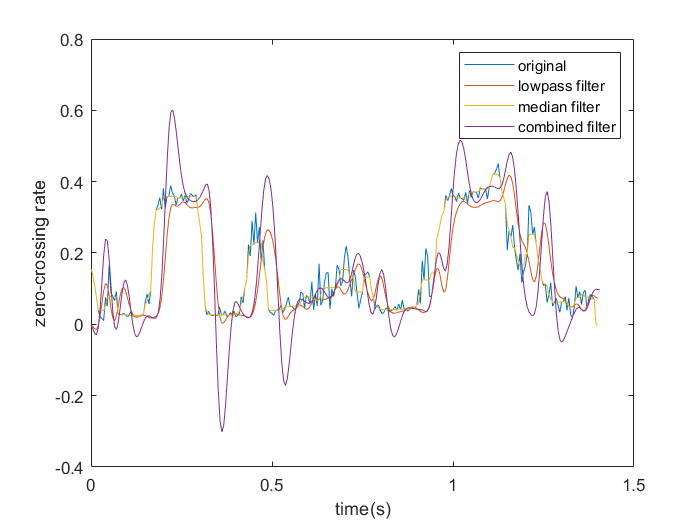


figure
plot(0:1/fs*R:(N/R-1)/fs*R,Z); hold on;
plot(0:1/fs*R:(N/R-1)/fs*R,Z_lowpass);hold on;
plot(0:1/fs*R:(N/R-1)/fs*R,Z_median_5);hold on;
plot(0:N/fs/(length(y)-1):N/fs,y);
legend('original','lowpass filter','median filter','combined filter');
xlabel('time(s)');
ylabel('zero-crossing rate');